% Load the CSV data
data_spot_odom = readtable('./spot_odometry_corrected.csv');
data_spot_est = readtable('./spot_pose.csv');
timestamp_spot_odom = (data_spot_odom{:,2}-data_spot_odom{1,2});
timestamp_spot_est = (data_spot_est{:,1}-data_spot_est{1,1});

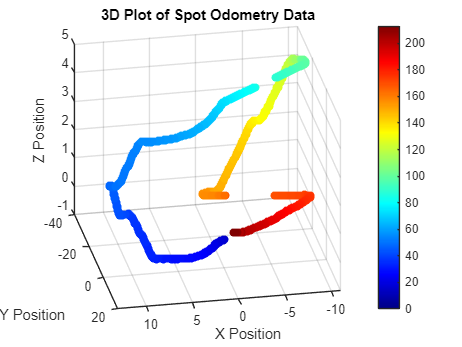

% --------------------- Odometry Data ------------------- 
% Extract position columns 
x_odom = data_spot_odom.pose_position_x; 
y_odom = data_spot_odom.pose_position_y; 
z_odom = data_spot_odom.pose_position_z; 

% Offset positions to start at (0,0,0) 
x_odom = x_odom - x_odom(1); 
y_odom = y_odom - y_odom(1); 
z_odom = z_odom - z_odom(1);

% Normalize timestamps for coloring 
timestamp_odom_norm = (timestamp_spot_odom - min(timestamp_spot_odom)) / (max(timestamp_spot_odom) - min(timestamp_spot_odom));

% Plot the 3D trajectory 
figure; 
scatter3(x_odom, y_odom, z_odom, 36, timestamp_spot_odom, 'filled'); 
colormap(jet); 
colorbar;
grid on;
xlabel('X Position'); 
ylabel('Y Position'); 
zlabel('Z Position'); 
title('3D Plot of Spot Odometry Data');

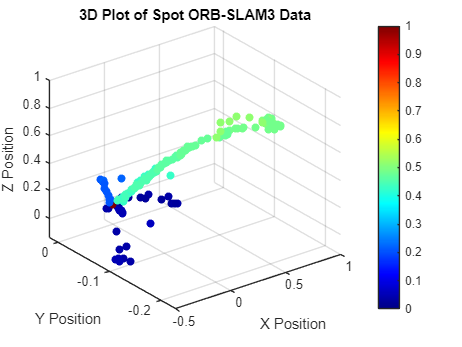

% --------------------- ORB-SLAM3 Pose Estimation Data ------------------- 
% Extract position columns 
x_est = data_spot_est.Var4; 
y_est = data_spot_est.Var5; 
z_est = data_spot_est.Var6; 


% Offset positions to start at (0,0,0) 
x_est = x_est - x_est(1); 
y_est = y_est - y_est(1); 
z_est = z_est - z_est(1);

% Normalize timestamps for coloring 
timestamp_est_norm = (timestamp_spot_est - min(timestamp_spot_est)) / (max(timestamp_spot_est) - min(timestamp_spot_est));

% Plot the 3D trajectory 
figure; 
scatter3(x_est, y_est, z_est, 36, timestamp_est_norm, 'filled'); 
colormap(jet); 
colorbar;
grid on;
xlabel('X Position'); 
ylabel('Y Position'); 
zlabel('Z Position'); 
title('3D Plot of Spot ORB-SLAM3 Data');